# Coupled Attitude and Orbit Motion to generate data (various shapes) for confirmation of the difference

## note

運動を確認するためのdata作成

- freeMotion

- boxWing

- boxOneWing

- box

以上の姿勢の時間履歴を/data/traindata, /data/validdataに出力する

freeMotioin: 外乱を無視した姿勢の時間履歴を出力．慣性モーメントと質量のみによって運動が決まる？（形状に依存しない）

output is csv:

 [Y, X] = [t_, mApp, r, v, q1, q2, q3, q4, w1, w2, w3], shape=(tspan, 15)

軌道要素も入れた

## revisions

@July 8 2023, hara

clc
clear
close all

### add path to use functions

curdir = pwd;
addpath(strcat(curdir, '/../WOBJ_toolbox_Version2b/'));
addpath(strcat(curdir, '/obj_data'));
addpath(genpath(strcat(curdir, '/../../hara_functions/')));
addpath(genpath(strcat(curdir, '/../../yoshimuLibrary/'))); % genpathでサブディレクトリ以下全てのpathを取得
% addpath(strcat(curdir, '/functions/'));

% create directory
mkdir ../../data/traindata/freeMotion/

mkdir ../../data/traindata/boxWing/

mkdir ../../data/traindata/boxOneWing/

mkdir ../../data/traindata/box/


mkdir ../../data/validdata/freeMotion/

mkdir ../../data/validdata/boxWing/

mkdir ../../data/validdata/boxOneWing/

mkdir ../../data/validdata/box/

### clear the data directory

% shapes = ["freeMotion", "boxWing", "boxOneWing", "box"];
shapes = ["boxWing"];

traindatadir = strcat(curdir, '/../../data/traindata/');
validdatadir = strcat(curdir, '/../../data/validdata/')

validdatadir = '/Users/ryuihara/Documents/ku/master_research/codes_master/create_traindata/hara_codes/../../data/validdata/'

for i = 1:1:size(shapes, 2)
    cddir = strcat(traindatadir, shapes(1,i), '/')
    cd(cddir);
    delete *.csv
    if shapes(1, i) ~= "freeMotion"
        cddir = strcat(validdatadir, shapes(1,i), '/');
        cd(cddir);
        delete *.csv
    end
    cd(curdir)
end

cddir = "/Users/ryuihara/Documents/ku/master_research/codes_master/create_traindata/hara_codes/../../data/traindata/boxWing/"

### flags and constants

for j = 0:1:3
    TLE = 1;
    model = j;
    lcModel = 'AS' % Ashikhmin-Shirley model
    init_qw = 'q' % 初期条件で全球方向に振るものが，姿勢q or 角速度w

    

    const = orbitConst; % orbitConstの構造体に軌道運動の定数が定義されてる
    earthVSOP = vsopConst; % わからん．VSOP98の定数らしい

### satellite parameter

    % if model == 0
    %     objName = 'flatPlate.obj';
    %     nCompo = 1; % # of object in .obj file
    %     sat = readSC(objName, nCompo); % satellite shape and optical parameters
    % 
    %     sat.J = diag([10, 15, 20]); % moment of inertia, kgm^2
    %     sat.m = 50; % mass, kg
    %     sat.nu = ones(size(sat.faces, 1), 1) .* 800; % 反射特性．とりあえずべたうち
    %     sat.nv = ones(size(sat.faces, 1), 1) .* 800;
    %     sat.F0 = ones(size(sat.faces, 1), 1) .* 0.5; % フレネル反射率
    %     sat.kappa = 0.0 % thermal emissivity
    if model == 0 || model == 1
        objName = 'boxWing.obj'
        nCompo = 3; % # of object in .obj file
        sat = readSC(objName, nCompo) % satellite shape and optical parameters
        % if nCompo == 3
        %     sat.J = diag([55, 40, 65]); % moment of inertia, kgm^2
        %     sat.m = 100; % mass, kg
        % elseif nCompo == 2
        %     sat.J = diag([40, 35, 50]);
        %     sat.m = 80;
        % end
        sat.J = diag([55, 40, 65]);
        sat.m = 100;
        % optical parameters at wing (manually...)
        sat.Ca(193:end, :) = 0.1; % なんで193
        sat.Cd(193:end, :) = 0.6;
        sat.Cs(193:end, :) = 0.3;
        sat.nu = ones(size(sat.faces, 1), 1) .* 800; % とりあえずべたうち
        sat.nv = ones(size(sat.faces, 1), 1) .* 800;
        sat.F0 = ones(size(sat.faces, 1), 1) .* 0.5;
        sat.kappa = 0.0; % thermal emissivity
    elseif model == 2
        objName = 'boxOneWing.obj'
        nCompo = 2; % # of object in .obj file
        sat = readSC("boxWing.obj", nCompo) % satellite shape and optical parameters
        % if nCompo == 3
        %     sat.J = diag([55, 40, 65]); % moment of inertia, kgm^2
        %     sat.m = 100; % mass, kg
        % elseif nCompo == 2
        %     sat.J = diag([40, 35, 50]);
        %     sat.m = 80;
        % end
        sat.J = diag([55, 40, 65]);
        sat.m = 100;
        % optical parameters at wing (manually...)
        sat.Ca(193:end, :) = 0.1; % なんで193
        sat.Cd(193:end, :) = 0.6;
        sat.Cs(193:end, :) = 0.3;
        sat.nu = ones(size(sat.faces, 1), 1) .* 800; % とりあえずべたうち
        sat.nv = ones(size(sat.faces, 1), 1) .* 800;
        sat.F0 = ones(size(sat.faces, 1), 1) .* 0.5;
        sat.kappa = 0.0; % thermal emissivity
    elseif model == 3
        objName = 'box.obj'
        nCompo = 1; % # of object in .obj file
        sat = readSC("boxWing.obj", nCompo) % satellite shape and optical parameters
        % if nCompo == 3
        %     sat.J = diag([55, 40, 65]); % moment of inertia, kgm^2
        %     sat.m = 100; % mass, kg
        % elseif nCompo == 2
        %     sat.J = diag([40, 35, 50]);
        %     sat.m = 80;
        % end
        sat.J = diag([55, 40, 65]);
        sat.m = 100;
        % optical parameters at wing (manually...)
        sat.Ca(193:end, :) = 0.1; % なんで193
        sat.Cd(193:end, :) = 0.6;
        sat.Cs(193:end, :) = 0.3;
        sat.nu = ones(size(sat.faces, 1), 1) .* 800; % とりあえずべたうち
        sat.nv = ones(size(sat.faces, 1), 1) .* 800;
        sat.F0 = ones(size(sat.faces, 1), 1) .* 0.5;
        sat.kappa = 0.0; % thermal emissivity
    else
        error("invalid model flag");
    end
    showSC(sat, "Normal", "on") % visualize satellite

### Iteration

- 学習データの作り方（初期条件）を設定する

    
    if strcmp(init_qw, 'w')
        wStd = 0.1; % Standard deviation, deg/s
        wNorm = sqrt(0.1); % [deg/s] 角速度ベクトルのノルム
        w_degStep = 30; %[deg/s]
        
        % ノルム固定して角運動量ベクトルを9面全体に振って初期角速度作成
        % wIniTrain = wCover_h(sat.J, 1, 45);
        wIniTrain = wCoverSimple_h(sqrt(0.1), w_degStep); % input: wNorm[deg], degStep
        
        % wIniTest = wRand(sat.J, 1, 3); % test様で(-1, 1)一様分布からランダムな初期角速度を作成
        wIniTest = [-0.007889, 0.002230, 0.013789;
                    -0.021363, -0.002530, 0.004076;
                    deg2rad([0.1, -0.0, -0.3])];
        
        wIniData = [wIniTrain; wIniTest]; % train, test用の初期角速度を結合
        
        N = size(wIniData, 1);
    elseif strcmp(init_qw, 'q')
        e_degStep = 45; % [deg]
        theta_degStep = 45; % [deg]
        qIniTrain = qCover2_h(e_degStep, theta_degStep);

        N = size(qIniTrain, 1);
    end
    % N = 2;
    for i = 1:N % 各初期角速度について姿勢，軌道計算

#### initial condition

- attitude

        if strcmp(init_qw, 'w')
            wIni = wIniData(i, :);
            if i < N
                qIni = [0 0 0 1];
            else
                % なんでNのときの初期姿勢変えてるん→初期姿勢角が違う時のvalidationのためだ
                qIni = [0.191341716182545,0.191341716182545,-0.270598050073098,0.923879532511287]; % degstep45の時の00200のqIniと同じ
                % qIni = [0 0 0 1];
            end   
        elseif strcmp(init_qw, 'q')
            % wIni = [0, 0, deg2rad(sqrt(0.1))]; % 初期姿勢を振れば，慣性系から見た角速度は変わる．実質はz軸に沿ったSingle Spin 仮定と等価？
            wIni = deg2rad([0.1, -0.0, -0.3]); % UKFに無理矢理合わせてtry
            qIni = qIniTrain(i,:);
        end

- orbit    (tle.oe = $a {\rm [km]}, e,i {\rm [rad]},\Omega {\rm [rad]},\omega{\rm [rad]},M{\rm [rad]}
$)

        if TLE == 1
            tle = readTLE('JCSAT2.txt', const);
            tle.oe(2) = 0.0001;
        else
            a = 42164.91220781728; % [km]
            e = 0.000215800000000; % eccentricity
            inc = 0.000938987137573; % [rad]
            W = 4.918899828139163; % [rad]
            w = 0.876621287411436; % [rad]
            m = 1.585708419923936; % [rad]
    
            tle.oe = [a e inc W w m];
            tle.jd = 2.458535992836310e+06;
        end
    
        [rIni, vIni] = oe2rv(tle.oe, 1, const); % at inertial frame, km, km/s
        rIni = rIni .* 10^3; % [m]
        vIni = vIni .* 10^3; % [m/s]
        jd = tle.jd; % Julian day, day

- arrange

        % initial condition
        xIni = [rIni, vIni, qIni, wIni];
        tspan = 0:1:60*10;
        % tspan = 0:1:60*3;

#### observer location

        obsLon = deg2rad(130.216544); % longitude, [rad]
        obsLat = deg2rad(33.594649); % latitude, [rad]
        [obsPosECEF(1), obsPosECEF(2), obsPosECEF(3)] = sph2cart(obsLon, obsLat, const.RE); % 球面座標から直交座標へ
        obsPosECEF = obsPosECEF .* 10^3; % shape=(1, 3), [m]
    
        qECI2ECEF = earthNutationPrecessionQ(const.J2000, tle.jd, 4, const); % (Earth attitude) quaternion from ECI to ECEF % わからん．
        obsECI = qRotation(4, obsPosECEF, qInv(4, qECI2ECEF)); % observer @ECI, shape=(1, 3), [m]

#### ODE

        options = odeset('RelTol', 1e-10, 'AbsTol', 1e-10); % 相対的な精度誤差（計算解の正しい桁数を制御），絶対許容誤差（計算解と真の解との差を制御）
        if model == 0 % 外乱なしの運動
            [t_, x_] = ode45(@(t, x)eomCowellFree_h(t, x, const, earthVSOP, sat, jd), tspan, xIni, options);
        else
            [t_, x_] = ode45(@(t, x)eomCowellQ(t, x, const, earthVSOP, sat, jd), tspan, xIni, options);
        end

#### data handling

        jdHistory = tle.jd + s2day(t_); % time history in Julian day
        r = x_(:, 1:3); % [m], position at i-frame
        v = x_(:, 4:6); % [m/s], velocity at i-frame
        q = x_(:, 7:10); % quaternion w.r.t. inertial frame
        w = x_(:, 11:13); % [rad/s], angular rate w.r.t. inertial frame

#### Sun position and observer positions

        [lonSun, latSun, rSun] = sunLonLatR(jdHistory, const, earthVSOP);
        [sunPosI(:, 1), sunPosI(:, 2), sunPosI(:, 3)] = sph2cart(lonSun, latSun, au2km(rSun, const)); % [km]
        sunPosI = sunPosI .* 10^3; % [m]
        sunRel = sunPosI - r; % relative vec from sat to observer @inertial frame, shape=(n, 3), [m]
        sunPosB = qRotation(4, normRow(sunRel), q); % relative observer directional vectors @ inertial frame, shape=(n, 3)
    
        % observer locationと同じことやってそう→ いややぱ違いそう
        qECI2ECEF = earthNutationPrecessionQ(const.J2000, jdHistory, 4, const);
        obsECI = qRotation(4, kron(ones(length(jdHistory), 1), obsPosECEF), qInv(4, qECI2ECEF)); % observer position @ECI, shape=(n, 3), [m]
        obsRel = obsECI - r; % relative vec from sat to observer @inertial frame, shape=(n, 3), [m]
        obsB = qRotation(4, normRow(obsRel), q); % relative observer directional vectors @ inertial frame, shape=(n, 3), [m]

#### Light curves

        nu = shadow(r./10^3, sunPosI./10^3, const.RS, const.RE); % calc Earth's shadow
        [mApp, ~] = lc(sat, 4, q, r, obsECI, sunPosI, nu, lcModel); % relative magnitude
        fObs = magInv(mApp, vecnorm(obsRel, 2, 2));

#### define training data

        % define training data
        zyx = q2zyx(4, q);
        X = [r, v, q w]; % attitude
        Y = [t_, mApp]; % light curves   

#### save the data

        if model == 0
            fName = "freeMotion";
        else
            fName = objName(1:end-4); % exclude '.obj'
        end
        if strcmp(init_qw, 'w')
            if i <= size(wIniTrain, 1)
                savedir = strcat(curdir, "/../../data/traindata/", fName, "/");
            else
                savedir = strcat(curdir, "/../../data/validdata/", fName, "/");
            end
        elseif strcmp(init_qw, 'q')
            savedir = strcat(curdir, "/../../data/traindata/", fName, "/");
        end
        
        savename = strcat(savedir, fName, sprintf('%03d', i), '.csv');
        writematrix([Y, X], savename); % (t_, mApp, q1, q2, q3, q4, w1, w2, w3), shape=(tspan, 9)

    end

#### save (all) variables of the last data

lcModel = 'AS'

init_qw = 'q'

objName = 'boxWing.obj'

Reading Object file : boxWing.obj
  % Blender v2.83.1 OBJ File: 'boxWing.blend'
  %www.blender.org
Reading Material file : boxWing.mtl
  % Blender MTL File: 'boxWing.blend'
  % Material Count: 2
Finished Reading Material file
Finished Reading Object file


ans =    242     3


ans =    472     3


sat = struct with fields:
    vertices: [242×3 double]
       faces: [472×3 double]
        area: [472×1 double]
         pos: [472×3 double]
      normal: [472×3 double]
          uu: [472×3 double]
          uv: [472×3 double]
         qlb: [472×4 double]
          Ca: [472×1 double]
          Cd: [472×1 double]
          Cs: [472×1 double]


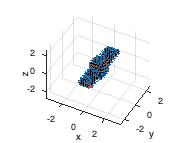

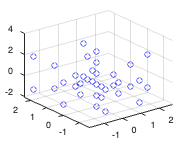

lcModel = 'AS'

init_qw = 'q'

objName = 'boxWing.obj'

Reading Object file : boxWing.obj
  % Blender v2.83.1 OBJ File: 'boxWing.blend'
  %www.blender.org
Reading Material file : boxWing.mtl
  % Blender MTL File: 'boxWing.blend'
  % Material Count: 2
Finished Reading Material file
Finished Reading Object file


ans =    242     3


ans =    472     3


sat = struct with fields:
    vertices: [242×3 double]
       faces: [472×3 double]
        area: [472×1 double]
         pos: [472×3 double]
      normal: [472×3 double]
          uu: [472×3 double]
          uv: [472×3 double]
         qlb: [472×4 double]
          Ca: [472×1 double]
          Cd: [472×1 double]
          Cs: [472×1 double]


lcModel = 'AS'

init_qw = 'q'

objName = 'boxOneWing.obj'

    "Reading Object file : "    "boxWing.obj"

  % Blender v2.83.1 OBJ File: 'boxWing.blend'
  %www.blender.org
    "Reading Material file : "    "boxWing.mtl"

  % Blender MTL File: 'boxWing.blend'
  % Material Count: 2
Finished Reading Material file
Finished Reading Object file


ans =    242     3


ans =    332     3


sat = struct with fields:
    vertices: [242×3 double]
       faces: [332×3 double]
        area: [332×1 double]
         pos: [332×3 double]
      normal: [332×3 double]
          uu: [332×3 double]
          uv: [332×3 double]
         qlb: [332×4 double]
          Ca: [332×1 double]
          Cd: [332×1 double]
          Cs: [332×1 double]


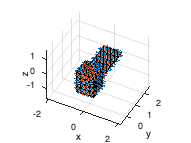

lcModel = 'AS'

init_qw = 'q'

objName = 'box.obj'

    "Reading Object file : "    "boxWing.obj"

  % Blender v2.83.1 OBJ File: 'boxWing.blend'
  %www.blender.org
    "Reading Material file : "    "boxWing.mtl"

  % Blender MTL File: 'boxWing.blend'
  % Material Count: 2
Finished Reading Material file
Finished Reading Object file


ans =    242     3


ans =    192     3


sat = struct with fields:
    vertices: [242×3 double]
       faces: [192×3 double]
        area: [192×1 double]
         pos: [192×3 double]
      normal: [192×3 double]
          uu: [192×3 double]
          uv: [192×3 double]
         qlb: [192×4 double]
          Ca: [192×1 double]
          Cd: [192×1 double]
          Cs: [192×1 double]


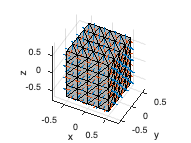

    fName = objName(1:end-4); % exclude '.obj'
    save(strcat(fName, '.mat'), 't_', 'mApp', 'q', 'zyx', 'w', 'r', 'v', 'obsECI', 'jdHistory', 'sat', 'obsRel', 'sunPosI')
    % zyx=(phi, theta, psi), obsRel: relative vec from sat to observer @ienrtial frame
end